## The impact of the EU-ETS on unemployment in France

### 0. Housekeeping

clear;
close all;

### 1. Data Importation 

Import Data Series:

- `GDP: INSEE/CNT-2020-PIB-EQB-RF/T.CNT-EQUILIBRE_PIB.SO.PIB.SO.VALEUR_ABSOLUE.FE.V.EUROS.CVS-CJO.FALSE`

- `Inflation: INSEE/IPCH-2015/M.IPCH.00.GLISSEMENT_ANNUEL.FE.SO.BRUT.2015.FALSE`

- `Unemployment: INSEE/CHOMAGE-TRIM-NATIONAL/T.CTTXC.TAUX.FM.0.00-.POURCENT.CVS.FALS`

% Quarterly data: unemployment rate, GDP
[output_q,~,T] = call_dbnomics('INSEE/CHOMAGE-TRIM-NATIONAL/T.CTTXC.TAUX.FM.0.00-.POURCENT.CVS.FALSE', 'INSEE/CNT-2020-PIB-EQB-RF/T.CNT-EQUILIBRE_PIB.SO.PIB.SO.VALEUR_ABSOLUE.FE.V.EUROS.CVS-CJO.FALSE');
% Monthly data: inflation
[output_m,~,T_m] = call_dbnomics('INSEE/IPCH-2015/M.IPCH.00.GLISSEMENT_ANNUEL.FE.SO.BRUT.2015.FALSE');

### 2. Data treatment

Transform monthly series to quarterly series

% Convert first columns to dates
dates = datetime(output_m(:,1), 'ConvertFrom', 'datenum');
values = output_m(:,2);
tt = timetable(dates, values);

% Transform monthly data into quarterly one
tt_q = retime(tt, 'quarterly', 'mean');

% Transform output back to array
tt_q_array = [datenum(tt_q.dates), tt_q.values];

Merge data into 1 dataframe

output = merge_dbnomics_outputs(output_q, tt_q_array);

Drop Na values and get index

idx = find(~isnan(sum(output(:,2:end),2)));
output = output(idx,:);
T = T(idx);

### 3. Create variables of interest

gy_obs  = diff(log(output(:,3))); % Output growth
pi_obs  = output(2:end,4); % Inflation rate
u_obs = output(2:end,2); % Unemployment rate
T = T(2:end);

### 4. Test stationnarity

1 means that we reject null hypothesis (ADF = 1 => stationnarity ; KPSS = 1 => non-stationnarity)

GDP growth: stationnary

adftest(gy_obs)

ans = logical
   1


kpsstest(gy_obs)

ans = logical
   0


Inflation: non-stationnary

adftest(pi_obs)

ans = logical
   0


kpsstest(pi_obs)

ans = logical
   1


Unemployment: non-stationnary

adftest(u_obs)

ans = logical
   0


kpsstest(u_obs)

ans = logical
   1


### 5. Plot variables

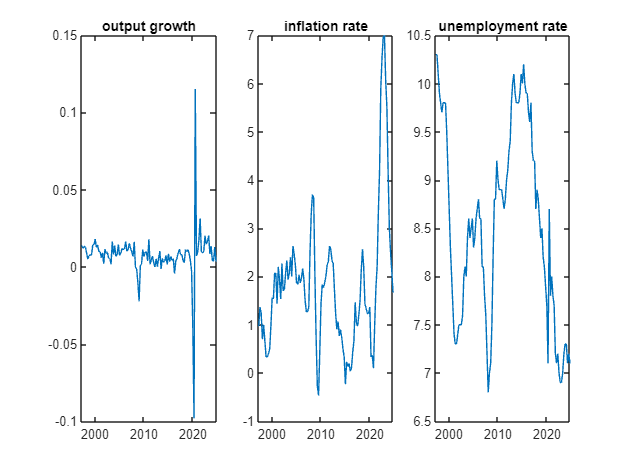

figure;
subplot(1,3,1)
plot(T,gy_obs)
xlim([min(T) max(T)]);
title('output growth')
subplot(1,3,2)
plot(T,pi_obs)
xlim([min(T) max(T)]);
title('inflation rate')
subplot(1,3,3)
plot(T,u_obs)
xlim([min(T) max(T)]);
title('unemployment rate')

### 6. Save variables in a matrix 

save myobs T gy_obs pi_obs u_obs;